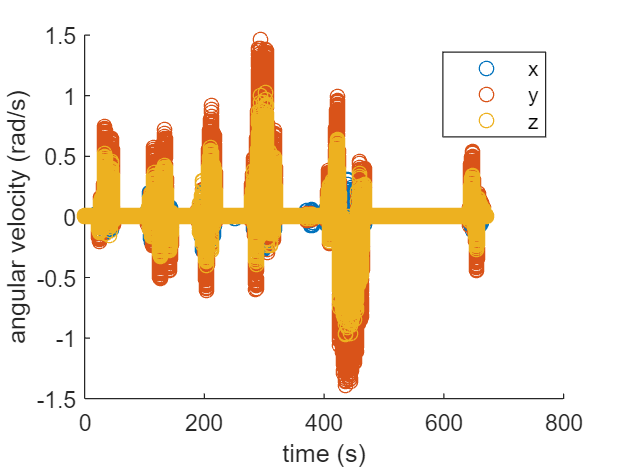

%% Import Test Data
opts = delimitedTextImportOptions("NumVariables", 7);
opts.DataLines = [5, Inf];
opts.Delimiter = ",";
opts.VariableNames = ["VarName1", "Main", "Main_1", "Main_2", "Main_3", "Main_4", "Main_5"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
accel42123 = readtable("accel_4_21_23.csv", opts);
accel42123 = table2array(accel42123);
clear opts

t_vec = accel42123(:,1);
w_vec = accel42123(:,2:4);
a_vec = accel42123(:,5:7);

%% View Data
figure;
scatter(t_vec,w_vec)

xlabel("time (s)")
ylabel("angular velocity (rad/s)")
legend("x","y","z")

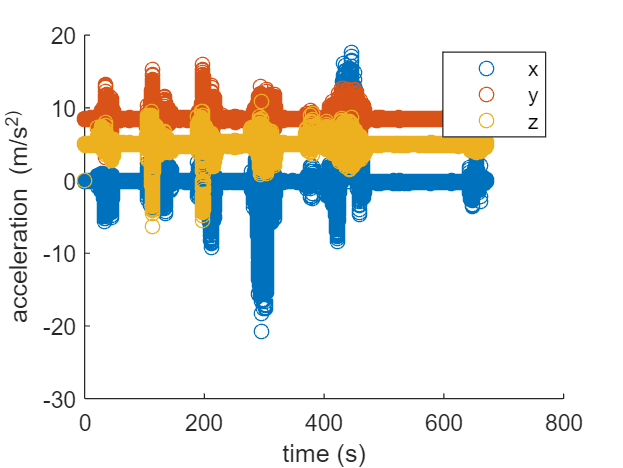


figure;
scatter(t_vec,a_vec)

xlabel("time (s)")
ylabel("acceleration (m/s^2)")
legend("x","y","z")

%% Set the value of the sensor and vehicle axis
%% NOTE: make sure norm(XYZs) = norm(XYZv) !!!
XYZs = [-0.21;8.47;5.01];
XYZv = [0;0;sqrt(dot(XYZs,XYZs))];

%% Compute the angle between the two axis using dot product formula
theta = acos(dot(XYZs,XYZv)/(norm(XYZv)^2));

    

%% Find an axis that is orthogonal to both axis using cross product, normalize
u = cross(XYZs,XYZv);
u = u/norm(u);

%% Compute cross product matrix
ux = [0 -u(3) u(2); u(3) 0   -u(1); -u(2) u(1) 0];

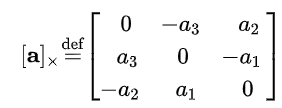    

%% Use Axis-Angle method to find the appropriate rotation matrix
R = (cos(theta)*eye(3)) + (sin(theta)*ux) + ((1-cos(theta))*(u*(u')));

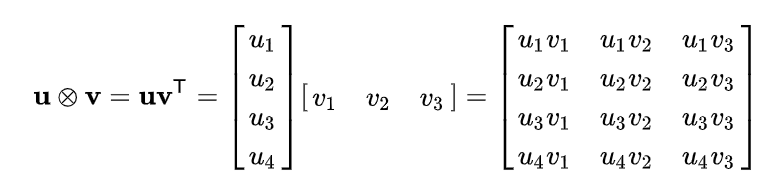

%% Test if the rotation matrix is correct
XYZr = R*XYZs;
error = abs(XYZr - XYZv)

error = 1.0e-16 *

    0.1388
         0
         0


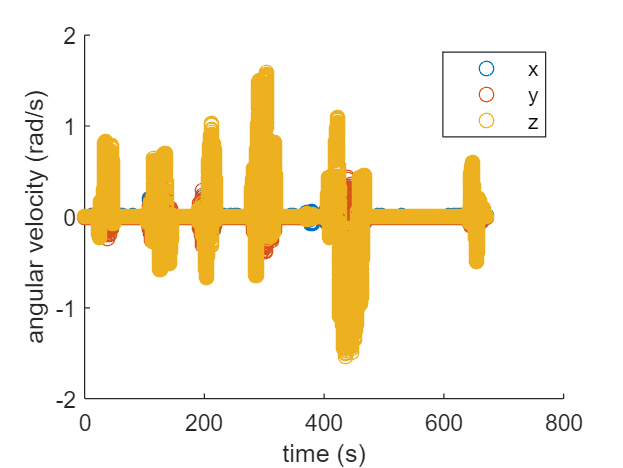


%% Adjust Axis for Accelerometer and Gyroscope
k = length(t_vec);

w_vec_v = ones(k,3);
a_vec_v = ones(k,3);

for i = 1:k
    w_vec_v(i,:) = R*(w_vec(i,:))';
    a_vec_v(i,:) = R*(a_vec(i,:))';
end

%% View Transformed Data
figure;
scatter(t_vec,w_vec_v)

xlabel("time (s)")
ylabel("angular velocity (rad/s)")
legend("x","y","z")

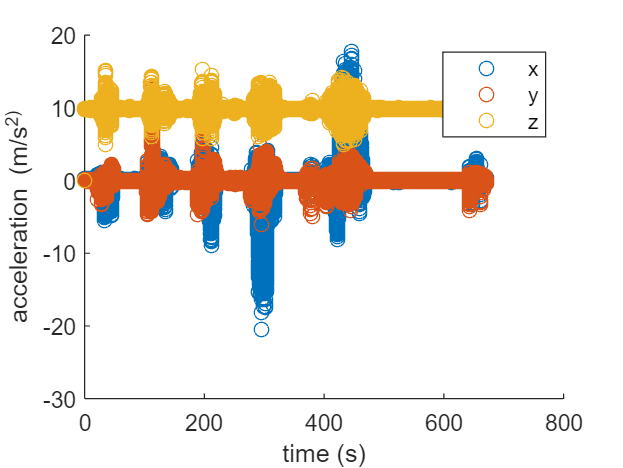


figure;
scatter(t_vec,a_vec_v)

xlabel("time (s)")
ylabel("acceleration (m/s^2)")
legend("x","y","z")